# **Title: Image Edge Detection **

## `Table of Contents`

        `1. Introduction`

        `2. User Inputs and Preprocessing Image`

        `3. Edge Detection`

        `  3.1 Canny Edge Detection`

        `  3.2 Roberts Edge Detection`

        `  3.3 Sobel Edge Detection`

            `3.4 Prewitt Edge Detection`

            `3.5 LoG Edge Detection`

            `3.6 zerocross Edge Detection`

            `3.7 kirsch Edge Detection`

            `3.8 craigs Edge Detection `

        `4. Displaying and Saving Results `

        `5. Conclusion`

## `1. Introduction`

Image edge detection plays a pivotal role in computer vision and image  processing, enabling the identification of boundaries within an image.  This MATLAB script explores various edge detection techniques, such as  Canny, Roberts, Sobel, Prewitt, LoG, zerocross, kirsch, and craigs. The  script aims to showcase their application on a given image and save the  results for further analysis.

##  `2. User Inputs and Preprocessing Image`

original_path = "/MATLAB Drive/sonika/sample.png"

original_path = "/MATLAB Drive/sonika/sample.png"

display_image = true

display_image = logical
   1


detector = "Roberts"

detector = "Roberts"

new_path = "output"

new_path = "output"


% reading image
img = imread(original_path);

% Converting the image to grayscale if it's in RGB
if size(img, 3) == 3
    grayImage = rgb2gray(img);
else
    grayImage = img; 
end

## `3. Edge Detection`

% Applying edge detection 
if detector == 'Canny-Sigma'
    edges = edge(grayImage, 'canny', [], 1.0);
elseif detector == 'Roberts-horizontal'
    edges = edge(grayImage, 'roberts', 'horizontal')
elseif detector == 'Roberts-vertical'
    edges = edge(grayImage, 'roberts', 'vertical');
else
    edges = edge(grayImage, detector);
end

## 4. Displaying and Saving Results

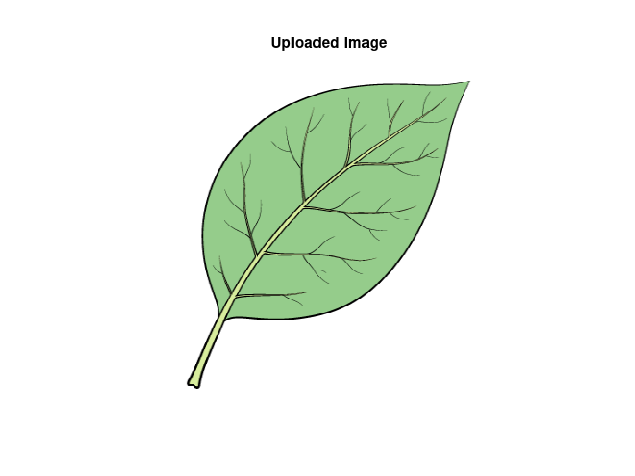

% Displaying orginal image
if display_image == 1
    figure;
    imshow(img);
    title('Uploaded Image');
end 

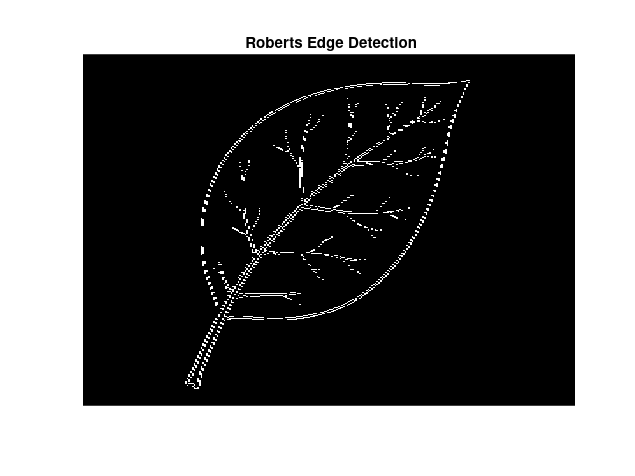


% Displaying and Saving image with edges
figure;
imshow(edges);
title(sprintf(' %s Edge Detection', detector));
saveas(gcf,  new_path+'.png');

## 5. Conclusion

In conclusion, this MATLAB script offers a comprehensive exploration of diverse edge detection methods, shedding light on their distinct applications and outcomes. The visualized results, saved for reference, provide valuable insights into the effectiveness of each technique. This script serves as a practical resource for image processing enthusiasts and researchers.